# BME3053C

# Final Project: Fracture Detection 

Authors/Group Members: Tisana Richards, Caleb Walton

Course: BME 3053C Computer Applications for BME

Term: Spring 2021

J. Crayton Pruitt Family Department of Biomedical Engineering

University of Florida

Emails: pgracias@ufl.edu, 

February 19, 2021

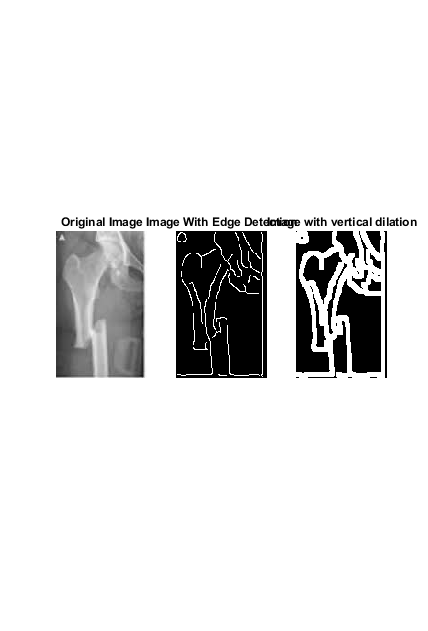

% some parts of the following code were inspired by msashawky https://www.google.com/url?q=https://github.com/msashawky/bone_fracture_detection_sample/blob/master/DIP%2520Final%2520Project.m&sa=D&source=editors&ust=1619135645411000&usg=AFQjCNES-WMStKtEOG7OsQ9VIUJidUCxxw
clc; clear;
%The code reads the image and converts it to grayscale if it is in RGB
A=input('Enter file name: ','s');
image=imread(A);
imshow(image);
IG=rgb2gray(image); % if image already in gray scale is added skip this line
imshow(IG);
filtered=imnoise(IG,'salt & pepper',0);
%This filter helps create noise around the bone structure which makes
%the white sillouette of skin darker
SE=strel('disk',3);
% strel used for dialation parameters
dilation=imdilate(filtered,SE); % dilation helps enhance the bone structure
c3=edge(dilation,'canny',0.2);% edge detection of the bone outline
imshow(c3);
se90=strel('line',5,90); % extra dilation strel
se0=strel('line',5,0);
Id=imdilate(c3,[se90 se0]); %  Extra dialation line is applied for better edge enhancement
imshow(Id);
subplot(1,3,1);% the following subplot sequence shows the process of the fracture detection
imshow(image);
title("Original Image");
subplot(1,3,2);
imshow(c3);
title("Image With Edge Detection");
subplot(1,3,3);
imshow(Id);
title("Image with vertical dilation");